## Setting parameters for the simulation

global beginIteration
global endIteration
global newSimulation
global receivedData;
global iteration
newSimulation = false;

if newSimulation
    eventBased = true;
    % beginIteration = 2150;
    % endIteration = 2350;
    % beginIteration = 3000;
    % endIteration = 3400;
    % beginIteration = 600;
    % endIteration = 700;
    beginIteration = 1;
    endIteration = height(bikeData{1});

    bikeData = loadBikeData();
    [newX, newY] = rotateCoordinates(bikeData{2}, -90);
    bikeData{2}.x = newX;
    bikeData{2}.y = newY;

    for i = 1:length(bikeData)
        bikeData{i}.("heading") = calculateHeading(bikeData{i});
        if eventBased
            bikeData{i}.toSend = determineEventBasedSending(bikeData{i});
        end
    end

    networkSimulator = wirelessNetworkSimulator.init;
    amountX = 3;
    amountY = 4;

    [grid, receivedData] = createGrid(amountX, amountY);
    bikes = setupBikes(grid)

    toReceive = determineToReceive(grid, bikeData);
    toReceive = [toReceive determineToReceiveBikes(bikes, bikeData, length(grid))];
    setListeners(grid, bikes);
   
    iteration = uint32(beginIteration);

    simulationData = struct;
    simulationData.bikeData = bikeData;
    simulationData.simulator = networkSimulator;
    simulationData.bikes = bikes;
    simulationData.traffic = traffic;
    addNodes(networkSimulator, grid);
    addNodes(networkSimulator, bikes);
    bikeStats = runSimulation(networkSimulator, simulationData);


    simulationTime = datetime;
    if eventBased
        save("Output\results\event_based_simulation_" + strrep(string(simulationTime), ":", ".") + ".mat")
    else
        save("Output\results\periodic_based_simulation_" + strrep(string(simulationTime), ":", ".") + ".mat")
    end
else
    % load("Output\results\event_based_simulation_15-1-2025_12.11.mat"); % Event-based with standard etsi specifications
    % load("Output\results\event_based_simulation_16-Jan-2025 15.15.23.mat"); % Event-based with minimum distance of 20 meters
    % load("Output\results\periodic_based_simulation_18-Jan-2025 12.21.54.mat");
    % load("Output\results\periodic_based_simulation_18-Jan-2025 23.48.43.mat"); % Latest periodic-based simulation
    load("Output\results\event_based_simulation_19-Jan-2025 13.01.22.mat"); % Latest event-based simulation
    % load("Output\results\periodic_based_simulation_22-Jan-2025 22.48.56.mat")
    newSimulation = false;
end

## Calculating package delivery ratio

fprintf("Node\tExpected\tReceived\tRatio")

Node	Expected	Received	Ratio

for i = 1:length(grid)
    [expected, received, ratio] = calculatePacketDeliveryRatio(grid{i}, toReceive{i});

    if ~isnan(expected)
        fprintf("%s:\t%d\t%d\t%.4f\n", grid{i}.Name, expected, received, ratio)
    end
end

Grid1:	61	54	0.8852
Grid5:	8	8	1.0000
Grid6:	50	48	0.9600
Grid8:	100	98	0.9800
Grid10:	102	93	0.9118
Grid14:	57	55	0.9649
Grid16:	31	30	0.9677
Grid17:	18	18	1.0000
Grid18:	22	18	0.8182
Grid19:	28	28	1.0000
Grid20:	38	38	1.0000


## Calculating MSE's

calculatedPositions = dictionary;

if ~eventBased
    for i = 1:length(bikeData)
        bikeData{i}.toSend = determineEventBasedSending(bikeData{i});
    end
    
    toReceive = determineToReceive(grid, bikeData);
end



for i=1:length(grid)
    if ~isempty(receivedData{grid{i}.Name})
        receivedBikes = unique(receivedData{grid{i}.Name}(1, :));
        receivedBikes = receivedBikes(receivedBikes <= length(grid) + length(bikes));
        
        calculatedPositions{grid{i}.Name} = dictionary;
        for bike = receivedBikes
        % for bike = 21
            dataReceived = [];

            for j = 1:length(receivedData{grid{i}.Name})
                if receivedData{grid{i}.Name}(1, j) == bike
                    dataReceived(end+1) = receivedData{grid{i}.Name}(2, j);
                end
            end

            dataExpected = [];

            for j = 1:length(toReceive{i})
                if toReceive{i}(1, j) == bike
                    dataExpected(end+1) = toReceive{i}(2, j);
                end
            end

            if ~isempty(dataExpected)
                calculatedPositions{grid{i}.Name}{bike} = calculatePositions(dataReceived, ...
                    dataExpected, bikeData{bike - length(grid)}, grid{i});
            end
        end
    end
end

for node=keys(calculatedPositions)'
    for bike = keys(calculatedPositions{node})'
        meanSquaredError = 0;
        for i = keys(calculatedPositions{node}{bike})'
            position = calculatedPositions{node}{bike}{i};
            meanSquaredError = meanSquaredError + ((bikeData{bike-length(grid)}.x(i) - position(1))^2 + ...
                (bikeData{bike-length(grid)}.y(i) - position(2))^2);
        end
        meanSquaredError = meanSquaredError/length(keys(calculatedPositions{node}{bike}));

        fprintf("Mean-Squared error for %s Bike%i: %.4f\n", node, bike - length(grid), meanSquaredError)
    end
end

Mean-Squared error for Grid1 Bike1: 52.6916
Mean-Squared error for Grid5 Bike2: 0.1649
Mean-Squared error for Grid6 Bike1: 0.0750
Mean-Squared error for Grid8 Bike2: 0.2163
Mean-Squared error for Grid10 Bike1: 3.5931
Mean-Squared error for Grid10 Bike2: 0.0112
Mean-Squared error for Grid14 Bike1: 0.0298
Mean-Squared error for Grid14 Bike2: 0.0000
Mean-Squared error for Grid16 Bike1: 0.0004
Mean-Squared error for Grid17 Bike2: 0.0000
Mean-Squared error for Grid18 Bike1: 5.8997
Mean-Squared error for Grid19 Bike1: 0.0000
Mean-Squared error for Grid20 Bike1: 0.0007


## Display calculated positions

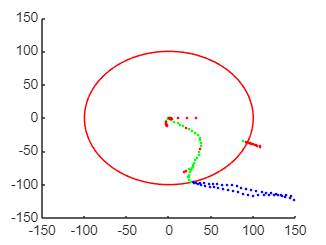

name = 'Output\figures\periodic predictions Grid1.tex'

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


figure

function plotOriginalData(bikeData)
    toPlotX = [bikeData.x(1)];
    toPlotY = [bikeData.y(1)];
    % scatter(bikeData.x(1), bikeData.y(1), 5, "filled", MarkerFaceColor="blue");
    for i = 2:height(bikeData)
        if bikeData.x(i) ~= bikeData.x(i-1) || bikeData.y(i) ~= bikeData.y(i-1)
            % scatter(bikeData.x(i), bikeData.y(i), 5, "filled", MarkerFaceColor="blue");
            toPlotX(end+1) = bikeData.x(i);
            toPlotY(end+1) = bikeData.y(i);
        end
    end
    scatter(toPlotX, toPlotY, 3, "filled", MarkerFaceColor="blue")
end

hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end

for i = 1:length(bikeData)
    plotOriginalData(bikeData{i})
end

for node=keys(calculatedPositions)'
    for bike = keys(calculatedPositions{node})'
        positions = cell2mat(values(calculatedPositions{node}{bike}))';

        positionsReceivedX = [];
        positionsReceivedY = [];
        positionsCalculatedX = [];
        positionsCalculatedY = [];


        for i = 1:length(positions)
            if positions(3, i)
                positionsReceivedX(end+1) = positions(1, i);
                positionsReceivedY(end+1) = positions(2, i);
            else
                positionsCalculatedX(end+1) = positions(1, i);
                positionsCalculatedY(end+1) = positions(2, i);
            end
        end

        scatter(positionsReceivedX, positionsReceivedY, 3, "filled", MarkerFaceColor="green")
        scatter(positionsCalculatedX, positionsCalculatedY, 3, "filled", MarkerFaceColor="red")
    end
end
hold off

% Saving the figure for
if newSimulation
    cleanfigure();
    if eventBased
        matlab2tikz('Output\figures\event-based predictions' + strrep(string(simulationTime), ":", ".") + '.tex')
    else
        matlab2tikz('Output\figures\periodic predictions' + strrep(string(simulationTime), ":", ".") + '.tex')
    end
end

% for i = 1:length(grid)
for i = 1
    x = grid{i}.Position(1);
    y = grid{i}.Position(2);
    xlim([x-150 x+150])
    ylim([y-150 y+150])
    name = 'Output\figures\event-based predictions Grid1.tex'
    matlab2tikz(name)
end

## Load data

function bikeData = loadBikeData()
    dataPath = fullfile("Data/location_data (1)");
    dataDirectory = dir(dataPath);
    bikeData = [];
    
    % for i = 3:length(dataDirectory)
    
    for i = 3:4 % The first to paths point to the directory itself and the top directory
        baseFileName = dataDirectory(i).name;
        fullFileName = fullfile(dataPath, baseFileName);
        table = readtable(fullFileName);
        bikeData{end+1} = table(:, [2, 5:15, 17]);
    end
    
    for i = 1:length(bikeData)
        bikeData{i}.("toSend") = true(height(bikeData{i}), 1);
    end

    % Calculating cartesian coordinates
    altitude = 30;  % 30 meters is an approximate altitude in Enschede
    origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), altitude];
    for i = 1:length(bikeData)
        [x, y] = calculateCartesianCoordinates(bikeData{i}, origin, altitude);
        bikeData{i}.("x") = x;
        bikeData{i}.("y") = y;
    end
end

Now, the GPS coordinates are converted to (x, y) coordinates.

## Calculating Cartesian coordinates from GPS data and rotating bike paths

function [x, y] = calculateCartesianCoordinates(bikeData, origin, altitude)
    % altitude = 30;  % 30 meters is an approximate altitude in Enschede
    % origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), altitude]; % The first location 
    % hold on
    [x,y] = latlon2local(bikeData.latitude, bikeData.longitude, altitude, origin);
    % hold off

    % hold off
end

function [x, y] = rotateCoordinates(bikeData, angle)
    newCoordinates = line(bikeData.x, bikeData.y);
    rotate(newCoordinates, [0 0 1], angle);
    x = transpose(newCoordinates.XData);
    y = transpose(newCoordinates.YData);
end

figure

hold on
for i = 1:length(bikeData)
    plot(bikeData{i}.x, bikeData{i}.y)
    % scatter(bikeData{i}.x, bikeData{i}.y, 10, "filled", MarkerFaceColor="blue");
end
% hold off


function headings = calculateHeading(bikeData)
% for i = 1:length(bikeData)
    headings = zeros(height(bikeData), 1);
    for j = 2:height(bikeData)
        currentPos = table2array(bikeData(j, ["x", "y"]));
        previousPos = table2array(bikeData(j-1, ["x", "y"]));
        if currentPos ~= previousPos
            heading = [currentPos(1) - previousPos(1), ...
                currentPos(2) - previousPos(2)];
            headings(j) = rad2deg(atan2(heading(2), heading(1)));
        else
            headings(j) = headings(j-1);
        end
    end
end

## Creating grid of listener nodes

function [nodes, receivedData] = createGrid(amountX, amountY)
    distance = 300;
    nodes = [];
    storageArray = [];
    nodeNames = string;
    nodeID = 1;

    for y = 0:distance:amountY*distance
        for x = 0:distance:amountX*distance
            config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeID,4),...
                NetworkTransmissions=1);
            node = bluetoothLENode("broadcaster-observer", Name="Grid" + nodeID);
            node.Position = [x -y 0];
            nodes{end+1} = node;
            storageArray{nodeID} = uint32.empty(2, 0);
            nodeNames(nodeID) = node.Name;
            nodeID = nodeID + 1;
        end
    end

   receivedData = dictionary(nodeNames, storageArray);
end

function h = circle(x,y,r)
    % % hold on
    % th = 0:pi/50:2*pi;
    % xunit = r * cos(th) + x;
    % yunit = r * sin(th) + y;
    % h = plot(xunit, yunit, Color="red", MarkerSize=0.1);
    % hold off
    drawcircle(Center=[x, y], Radius=r, Color='red', InteractionsAllowed='none', FaceAlpha=0, LineWidth=1);
end

% hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end
hold off

% cleanfigure()
% matlab2tikz('Output\figures\bike_route.tex');

## Determining which messages to send

function toSend = determineEventBasedSending(bikeData)
    global beginIteration
    global endIteration

    maxGenerateTime = 5000; % the maximum time between two transmitted messages, which is 5000 ms
    minDistance = 4; % minimum change in distance after last transmitted message, which is 4 meters
    minSpeedChange = 5; % minimum speed change between after last transmitted message, which is 5 m/s
    minheadingChange = 4; % minimum change in heading after last transmitted message, which is 4 degrees
    
    % indicesInRange = toReceive;
    toSend = bikeData.toSend;
    
    lastMessage = beginIteration;
    
    for i = beginIteration:endIteration
        if bikeData.timestamp_ms(i) >= bikeData.timestamp_ms(lastMessage) + maxGenerateTime
            lastMessage = i;
            toSend(i) = true;
        elseif pdist2(bikeData{i, ["x" "y"]}, bikeData{lastMessage, ["x" "y"]}) >= minDistance
            lastMessage = i;
            toSend(i) = true;
        elseif abs(bikeData.velocity(i) - bikeData.velocity(lastMessage))/3.6 >= minSpeedChange
            lastMessage = i;
            bikeData.toSend(i) = true;
        elseif abs(bikeData.heading(i) - bikeData.heading(lastMessage)) >= minheadingChange
            lastMessage = i;
            toSend(i) = true;
        else
            toSend(i) = false;
        end
    end
end



## Determine which messages each listener node should receive

function x = inRange(position1, position2)
    distance = pdist2(position1, position2);
    x = distance < 100;
end

function toReceive = determineToReceive(grid, bikeData)
    global beginIteration
    global endIteration
        
    for k = 1:length(grid)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            for j = beginIteration:endIteration
                messagePosition = [bikeData{i}.x(j) bikeData{i}.y(j)];
                if (inRange(grid{k}.Position([1 2]), messagePosition)) && (bikeData{i}.toSend(j))
                    toReceive{k}(:, end + 1) = [uint32(length(grid) + i) uint32(j)];
                end
            end
        end
    end
end

function toReceive = determineToReceiveBikes(bikes, bikeData, gridLength)
    global beginIteration
    global endIteration

    for k = 1:length(bikes)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            if i ~= k
                for j = beginIteration:endIteration
                    position1 = [bikeData{k}.x(j) bikeData{k}.y(j)];
                    position2 = [bikeData{i}.x(j) bikeData{i}.y(j)];
                    if inRange(position1, position2) && bikeData{i}.toSend(j)
                        toReceive{k}(:, end + 1) = [uint32(gridLength + i) uint32(j)];
                    end
                end
            end
        end
    end
end


## Setup simulation

function bikes = setupBikes(grid)
    global receivedData
    config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(length(grid)+1, 4),...
            NetworkTransmissions=1, Relay=false);
    
    bike1 = bluetoothLENode("broadcaster-observer", Name="Bike1", MeshConfig=config);
    bike2 = bluetoothLENode("broadcaster-observer", Name="Bike2", MeshConfig=config);
    
    receivedData(bike1.Name) = {uint32.empty(2, 0)};
    receivedData(bike2.Name) = {uint32.empty(2, 0)};
    
    bikes = {bike1 bike2};
    
    % toReceive = [toReceive determineToReceiveBikes(bikes, bikeData, length(grid))];
    
    global traffic
    traffic = dictionary;
    
    for i = 1:length(bikes)
        traffic{bikes{i}.Name} = networkTrafficOnOff(OnTime=0.02, OffTime=0.08, PacketSize=8, GeneratePacket=true, DataRate=10);
        addTrafficSource(bikes{i}, traffic{bikes{i}.Name}, ...
            SourceAddress=bikes{i}.MeshConfig.ElementAddress, ...
            DestinationAddress=grid{5}.MeshConfig.ElementAddress);
    end
end

Create listener to process received data

function processData(Node, EventData)
    global receivedData;
    message = EventData.Data.Message;

    received_id = typecast(uint8(transpose(message)), 'uint32');
    receivedData{Node.Name}(:, end+1) = received_id;
end

function setListeners(grid, bikes)
    for i = 1:length(grid)
        addlistener(grid{i}, "MeshAppDataReceived", @processData);
    end
    
    for i = 1:length(bikes)
        addlistener(bikes{i}, "MeshAppDataReceived", @processData);
    end
end

Create function which sets position of the bike 

function sendData(~, userData)
    global iteration;

    for i = 1:(length(userData.bikes))
        if userData.bikeData{i}.toSend(iteration)
            userData.bikes{i}.Position = [userData.bikeData{i}.x(iteration) ...
                userData.bikeData{i}.y(iteration) 0];
            
            bytes = typecast([userData.bikes{i}.ID iteration], "uint8");
            userData.traffic{userData.bikes{i}.Name}.ApplicationData = bytes;
            userData.traffic{userData.bikes{i}.Name}.OffTime = 0;
        else
            userData.traffic{userData.bikes{i}.Name}.OffTime = ...
                userData.traffic{userData.bikes{i}.Name}.OffTime + 0.1;
        end
    end
    
    iteration = iteration + 1;
end


% scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);

Bluetooth messages will now be simulated

## Run simulation

function stats = runSimulation(networkSimulator, simulationData)
    global beginIteration
    global endIteration
    global iteration
    global receivedData


    
    % addNodes(networkSimulator, grid);
    % addNodes(networkSimulator, bikes);
    scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);


    simulationTime = (endIteration - beginIteration) / 10
    startTime = datetime;
    fprintf("%s: Starting simulation\n", startTime)
    run(networkSimulator,simulationTime);
    endTime = datetime;
    fprintf("%s: Simulation ended", endTime)
    iteration

    
    
    stats = [];
    for i=1:length(networkSimulator.Nodes)
        stats{i} = statistics(networkSimulator.Nodes{i});
    end
end

function [expected, correctlyReceived, fractionCorrect] = calculatePacketDeliveryRatio(node, expectedMessages)
    global receivedData
    totalReceived = 0;
    totalExpected = 0;

    expected = NaN;
    correctlyReceived = NaN;
    fractionCorrect = NaN;

    % for i = 1:length(toReceive)
        if length(expectedMessages) >= 1
            % fprintf("%i: Data of %s:", i, networkSimulator.Nodes{i}.Name)
            received = unique(receivedData{node.Name}.', "rows").';
            correctlyReceived = 0;
            expected = length(expectedMessages);
        
            for j=1:length(expectedMessages)
                % toReceive{i}(:, j)
                % receivedData{networkSimulator.Nodes{i}.Name}
                if ismember(expectedMessages(:, j)', receivedData{node.Name}', "rows")
                    correctlyReceived = correctlyReceived + 1;
                end
            end
            
            correctlyReceived;
            fractionCorrect = correctlyReceived/length(expectedMessages);

            totalReceived = totalReceived + correctlyReceived;
            totalExpected = totalExpected + length(expectedMessages);
        end
    
    % totalExpected
    % totalReceived
    totalFractionCorrect = totalReceived/totalExpected;
end


% runSimulation(networkSimulator, toReceive)
% bike1Stats = statistics(bike1)
% gridStats = statistics(grid{1})
% grid2Stats = statistics(grid{2})


## Running simulation

## Calculate next position

function [x, y] = getNextPosition(previousPostition, speed, heading, duration)
    if nargin <= 3
        duration = 1;
    end
    distanceMoved = (speed/3.6)*duration;
    x = previousPostition(1) + distanceMoved * cosd(heading);
    y = previousPostition(2) + distanceMoved * sind(heading);
end

function calculatedPositions = calculatePositions(receivedMessages, expectedMessages, bikeData, node)
    calculatedPositions = dictionary;
    lastPosition = bikeData{expectedMessages(1), ["x" "y"]};
    speed = bikeData.velocity(expectedMessages(1));
    heading = bikeData.heading(expectedMessages(1));

    i = expectedMessages(1);
    index = 2;
    
    while i < expectedMessages(end)

        if ismember(i, receivedMessages)
            lastPosition = [bikeData{i, ["x" "y"]} true];
            speed = bikeData.velocity(i);
            heading = bikeData.heading(i);
        else
            [x, y] = getNextPosition(lastPosition, speed, heading);
            lastPosition = [x, y, false];
        end
        calculatedPositions{i} = lastPosition;
        
        
        if expectedMessages(index) <= i + 10
            i = expectedMessages(index);
            index = index + 1;
        elseif inRange(bikeData{i + 10, ["x" "y"]}, node.Position(1:2))
            i = i + 10;
        else
            i = expectedMessages(index);
            index = index + 1;
        end
    end
end

## Calculating mean squared error

## Displaying the calculated positions



% legend("Original, not received", "Received message", "Predicted location")

% matlab2tikz('Output\figures\event-based predictions.tex');
% matlab2tikz('Output\figures\periodic predictions.tex');